clc, clearvars, close all
% Synthesis of H infty regulator for synchronous mode, requiers TDS toolbox:
% https://gitlab.kuleuven.be/u0011378/tds-control

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



% Parameters
p = params();
cellfun(@(f) assignin('caller',f,p.(f)), fieldnames(p));


omega_p = omega_nom;

% Operating point
fun = @(x) steady_equations(x, p, omega_p, 0.9*Pn_el/omega_p);
x0 = [1; 0.2];

sol = fsolve(fun, x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>




V_p = sol(1);
u_p = sol(2);

Q_p = A * V_p;
hf_p = f*L/(2*D*g)*V_p^2;
Hb_p = HL - hf_p;

fprintf('Working point:\n');

Working point:


fprintf('V_p = %.3f m/s\n', V_p);

V_p = 2.626 m/s


fprintf('u_p = %.3f\n', u_p);

u_p = 0.909


fprintf('Q_p = %.3f m3/s\n', Q_p);

Q_p = 41.766 m3/s


fprintf('Hb_p = %.3f m\n', Hb_p);

Hb_p = 169.750 m



% Linearization

B  = (g*A)/a;
Kh = (k*u_p)/(2*sqrt(Hb_p-Ht));
Ku = k*sqrt(Hb_p-Ht);
CQ = (rho*g*eta_t)*(Hb_p-Ht)/omega_p;
CH = (rho*g*eta_t)*Q_p/omega_p;
Cw = (rho*g*eta_t)*Q_p*(Hb_p-Ht)/omega_p^2;
Dw = b+c*omega_p; % linearization of losses
T  = I/(Cw+Dw);
tau = (Nx-1)*dt;

delay = exp(-2*tau*s);

num_h = (B*CQ - CH) + (B*CQ + CH)*delay;
den_h = (Kh + B) + (B - Kh)*delay;

G_h = Ku * num_h / den_h;
G_f    = 1 / (Tw*s + 1);


G_mech = 1 / ((Cw+Dw)*(T*s + 1));
G = G_h*G_f;

%%% State space - sync mode
a0 = Kh+B;
a1 = B-Kh;
b0 = Ku*(B*CQ-CH);
b1 = Ku*(B*CQ+CH);
delta = 2*tau;

% State space matrices
A1p = [-1/Tw];
A2p = [-a1/(a0*Tw)];
H1p = [a1/a0];
B11p = [b0/(a0*Tw)];
B12p = [b1/(a0*Tw)];
Cp = (1/Pn_el)*[1]; % scale by systems dcgain, for Bode use Cp = 1

sys = tds_create_neutral({H1p},delta,{A1p,A2p},[0 delta],{B11p, B12p},[0 delta],{1},0);
disp('Poles of the neutral system: ')

Poles of the neutral system: 


roots = tds_roots(sys,[-80 0 -1800 1800])

Degree of the spectral discretisation is 230.


roots = 1.0e+03 *

  -0.0111 + 1.7868i
  -0.0111 - 1.7868i
  -0.0111 + 1.7593i
  -0.0111 - 1.7593i
  -0.0111 + 1.7318i
  -0.0111 - 1.7318i
  -0.0111 + 1.7043i
  -0.0111 - 1.7043i
  -0.0111 + 1.6768i
  -0.0111 - 1.6768i


disp('Zeros of the neutral system: ')

Zeros of the neutral system: 


options = tds_roots_options('max_size_evp', 2000);
nul = tds_tzeros(sys,[0 200 -1800 1800],options)

Degree of the spectral discretisation is 237.


nul = 1.0e+03 *

   0.0040 + 1.5944i
   0.0040 - 1.5944i
   0.0040 + 0.7972i
   0.0040 - 0.7972i
   0.0040 + 0.0000i



tol = 1e-12;

% rozdělení pólů podle Re(lambda)
rr = roots(real(roots) > tol);
rg = roots(real(roots) < -tol);
rb = roots(abs(real(roots)) <= tol);

% rozdělení nul podle Re(lambda)
lr = nul(real(nul) > tol);
lg = nul(real(nul) < -tol);
lb = nul(abs(real(nul)) <= tol);


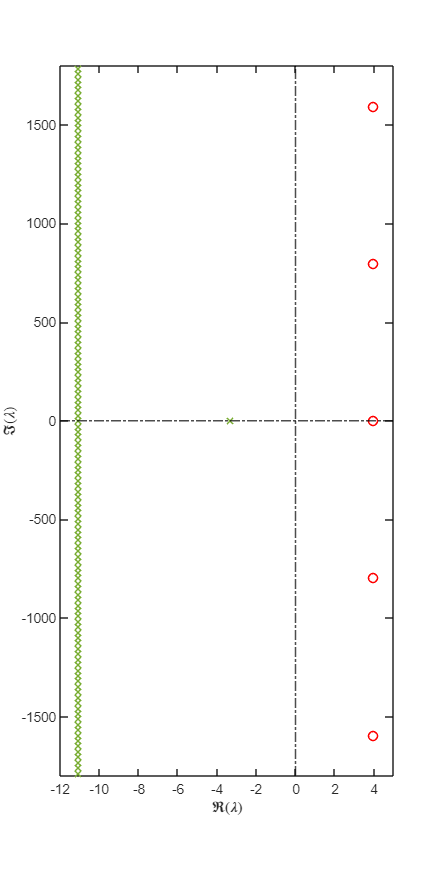

% PZ Map - modified function based on tds_eigenplot
figure; hold on; box on;

% poly
if ~isempty(rr)
    plot(real(rr), imag(rr), 'rx', 'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(rg)
    plot(real(rg), imag(rg), 'x', ...
        'Color',[0.4660 0.6740 0.1880], ...
        'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(rb)
    plot(real(rb), imag(rb), 'bx', ...
        'MarkerSize',6, 'LineWidth',1);
end

% nuly
if ~isempty(lr)
    plot(real(lr), imag(lr), 'ro', 'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(lg)
    plot(real(lg), imag(lg), 'o', ...
        'Color',[0.4660 0.6740 0.1880], ...
        'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(lb)
    plot(real(lb), imag(lb), 'bo', ...
        'MarkerSize',6, 'LineWidth',1);
end

xlim([-12 5]);
ylim([-1800 1800]);
xticks(-12:2:5)

xline(0,'k-.','LineWidth',1)
yline(0,'k-.','LineWidth',1)

xlabel('$$\Re(\lambda)$$','Interpreter','latex')
ylabel('$$\Im(\lambda)$$','Interpreter','latex')


grid off
set(gca,'FontSize',9,'GridAlpha',0.2)

set(gcf,'Units','centimeters');
set(gcf,'Position',[0 0 12 24]);


%exportgraphics(gcf,'poles_zeros_sync.pdf','ContentType','vector','Resolution',300);

Ex = eye(1)+H1p;
Ax = (A1p + A2p);
Bx = (B11p + B12p);

sys0 = ss(Ax,Bx,Cp,0,'E',Ex);
disp(['DC gain of the neutral system: ',num2str(freqresp(sys0,0),3)])

DC gain of the neutral system: 0.0272


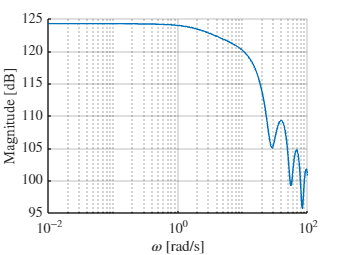



sys = tds_create_neutral({H1p}, delta, {A1p, A2p}, [0 delta], ...
    'B2', {B11p, B12p}, [0 delta], ...
    'C2', {1}); % Cp = 1

% Frequency range
W = logspace(-2, 2, 500);   % rad/s

% Singular Values (SISO)
SV = tds_sigma(sys, W);

% dB
SV_dB = 20*log10(SV);

figure;

semilogx(W, SV_dB, 'LineWidth',1);
grid on
box off

xlabel('$\omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('Magnitude [dB]','Interpreter', 'latex')

set(gca,'TickLabelInterpreter','latex') 

set(gca, 'XScale', 'log');
xlim([1e-2 1e2]);

set(gca,'FontSize',9,'GridAlpha',0.2)

% velikost pro LaTeX
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);

% export
%exportgraphics(gcf, 'bode_ampl_sync.pdf', 'ContentType','vector','Resolution',300);

%%% Augumented plant


% Weights 
% State space W1
W1 = ss(0.678*((s/2.5)+0.2)/(s+0.2));


Aw1 = W1.A;
Bw1 = W1.B;
Cw1 = W1.C;
Dw1 = W1.D;

% State space W3

W3 = ss(3*(0.1119*s+0.2239)/(0.206*s+1));

Aw3 = W3.A;
Bw3 = W3.B;
Cw3 = W3.C;
Dw3 = W3.D;



% Second order W3
nu_p = size(A1p,1);
nu_w1 = size(Aw1,1);
nu_w3 = size(Aw3,1);


A1e = [
A1p zeros(nu_p,nu_w1+nu_w3);
-Bw1*Cp Aw1 zeros(nu_w1,nu_w3);
Bw3*Cp zeros(nu_w3,nu_w1) Aw3
];

A2e = [
A2p zeros(nu_p,nu_w1+nu_w3);
zeros(nu_w1+nu_w3,nu_p+nu_w1+nu_w3)
];

% B11e, B12e
B11e = [B11p; zeros(nu_w1+nu_w3,1)];
B12e = [B12p; zeros(nu_w1+nu_w3,1)];

% B21e
B2e = [
zeros(nu_p,1);
Bw1;
zeros(nu_w3,1)
];

% H1e
H1e = [
H1p zeros(nu_p,nu_w1+nu_w3);
zeros(nu_w1+nu_w3,nu_p+nu_w1+nu_w3)
];

% C11e
C1e = [-Cp zeros(1,nu_w1+nu_w3)];

% C21e
C2e = [
-Dw1*Cp Cw1 zeros(1,nu_w3);
Dw3*Cp zeros(1,nu_w1) Cw3
];

% D22,1e
D22 = [
Dw1;
0
];
% D11,1e
D11 = 0;
% D12,1e
D12 = 1;
% D21,1e
D21 = [0;0]

D21 =      0
     0



sys = tds_create_neutral({H1e},delta,{A1e,A2e},[0 delta],{B11e, B12e},[0 delta],{C1e},0,...
'D12',{D12},'B2',{B2e},'C2',{C2e},'D22',{D22})

sys = LTI Neutral Time-Delay State-Space System with properties:

       H: {[3×3 double]}
      hH: 0.2286
      mH: 1
       A: {[3×3 double]  [3×3 double]}
      hA: [0 0.2286]
      mA: 2
      B1: {[3×1 double]  [3×1 double]}
     hB1: [0 0.2286]
     mB1: 2
      C1: {[-1.6667e-08 0 0]}
     hC1: 0
     mC1: 1
      B2: {[3×1 double]}
     hB2: 0
     mB2: 1
      C2: {[2×3 double]}
     hC2: 0
     mC2: 1
     D12: {[1]}
    hD12: 0
    mD12: 1
     D22: {[2×1 double]}
    hD22: 0
    mD22: 1
       n: 3
      p1: 1
      q1: 1
      p2: 1
      q2: 2


ny = 1; nu = 1; nc = 2;
% optimize everything via mask
mask  = ss(zeros(nc,nc), zeros(nc,nu), ones(nu,nc), 1);
s = tf('s');

C = pid(0.45,1,0.05,0.04);
C2 = pid(0.3,0.9,0.03,0.04);
C3 = pid(0.2,0.8,0.01,0.04);

C_ss = ss(C,'minimal');
basisA = C_ss.A;
basisB = C_ss.B;
basis = ss(basisA, basisB, zeros(nu,nc), 0);
initial1 = ss(C_ss.A,C_ss.B,C_ss.C, C_ss.D);
initial2 = ss(C2);
initial3 = ss(C3);

initial_cont = {initial1, initial2, initial3};

opts = tds_hiopt_options('nstart',3);
[K,cl] = tds_hiopt_dynamic(sys,nc,'options',opts,...
'initial',initial_cont,'basis',basis,'mask',mask);

Preliminary step: Making sure that the initial controllers are strongly stabilizing.
Initial controller 1 is stable.
Initial controller 2 is stable.
Initial controller 3 is stable.


Starting BFGS.
bfgs: iter 1: nfevals = 6, step = 3.2e+01, f = 6.7170000e-01, nG = 1, dnorm = 1.8e-15
bfgs: gradient norm below tolerance, quit at iteration 1, f = 6.7170000e-01
Line search failed to satisfy weak Wolfe conditions although point satisfying conditions was bracketed
bfgs: iter 1: nfevals = 32, step = 2.0e+00, f = 6.7527283e-01, nG = 1, dnorm = 1.0e-02
bfgs: quit at iteration 1, f = 6.7527283e-01, dnorm = 1.0e-02
bfgs: iter 1: nfevals = 6, step = 3.2e+01, f = 6.7170000e-01, nG = 1, dnorm = 2.3e-15
bfgs: gradient norm below tolerance, quit at iteration 1, f = 6.7170000e-01
Function values after BFGS: 6.717000e-01, 6.752728e-01, 6.717000e-01.



tds_strong_sa(cl, -10)

ans = -0.0265


opts_hinf = tds_hinfnorm_options( ...
    'fix_N', 10, ...
    'Ntheta', 10, ...
    'pred_tol', 1e-2, ...
    'newton_tol', 1e-4);

[ginf, wpeak] = tds_hinfnorm(cl, opts_hinf)

ginf = 0.6717

wpeak = 0

tds_roots(cl,[-80 0 -100 100])

Degree of the spectral discretisation is 21.


ans =  -11.0804 +82.6340i
 -11.0804 -82.6340i
 -11.0870 +55.2213i
 -11.0870 -55.2213i
 -11.1247 +27.9174i
 -11.1247 -27.9174i
 -22.8528 + 0.0000i
 -11.1610 + 0.0000i
  -0.0265 + 0.0000i
  -0.0265 + 0.0000i



sys = ss(K.A,K.B,K.C,K.D);
PID = pid(sys)

PID =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 0.844, Ki = 0.98, Kd = 0.0421, Tf = 0.04
 
Continuous-time PIDF controller in parallel form.
Model Properties


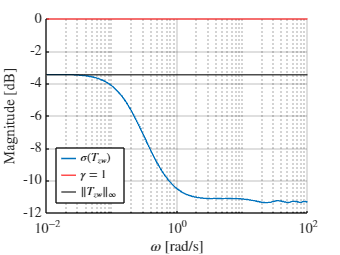

% Frequency range
W = logspace(-2, 2, 500);   % rad/s

% Singular values
SV_cl = tds_sigma(cl, W);

% dB
SV_cl_dB = 20*log10(SV_cl);

figure;

semilogx(W, SV_cl_dB, 'LineWidth',1);
grid on
box off

gamma = 1;

yline(20*log10(gamma),'r','\gamma = 1', ...
    'Interpreter','latex', ...
    'LineWidth',1);

yline(20*log10(ginf),'k', ...
    'Interpreter','latex', ...
    'LineWidth',1);

xlabel('$\omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('Magnitude [dB]','Interpreter', 'latex')

set(gca,'TickLabelInterpreter','latex') 

set(gca, 'XScale', 'log');
xlim([1e-2 1e2]);

set(gca,'FontSize',9,'GridAlpha',0.2)

lgd = legend({'$\sigma(T_{zw})$','$\gamma = 1$','$\|T_{zw}\|_\infty$'}, ...
    'Interpreter','latex','Location','southwest');
lgd.ItemTokenSize = [10 6];

set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);

% export
%exportgraphics(gcf, 'cl_sigma_sync.pdf','ContentType','vector','Resolution',300);